# LAB5

Seyyed Mohammad Matin Alemohammad (810197457)

Amirhossein Mohammadi (810197689)

clc
clear
close all
rng(1)
dcl_init

N = pkt_size;
M = 4; %4PSK
k = log2(M);
b_tx = bit_gen(N, k)

b_tx =      0     1
     1     0
     0     1
     0     1
     0     0
     0     0
     0     1
     0     1
     0     0
     1     0


b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


dec = bi2de(b_tx, 'left-msb');
dec_gray = bi2de(b_gray, 'left-msb');
sym_idx = zeros(N, 1);
if flg_gray_encode
    for i=1:M
        sym_idx(dec == dec_gray(i))= i-1;
    end
else
    sym_idx = dec;
end
disp(sym_idx);

     1
     3
     1
     1
     0
     0
     1
     1
     0
     3
     0
     2
     0
     2
     1
     3
     1
     3
     1
     0
     3
     2
     1
     3
     3
     3
     1
     0
     0
     2
     1
     1
     3
     2
     3
     0
     3
     2
     0
     3
     2
     2
     1
     2
     0
     0
     2
     1
     0
     0
     0
     2
     1
     0
     1
     1
     2
     1
     2
     3
     1
     1
     2
     1
     1
     2
     3
     3
     2
     3
     3
     1
     1
     2
     1
     0
     3
     1
     2
     3
     2
     2
     3
     1
     0
     3
     1
     2
     3
     2
     0
     2
     1
     3
     1
     0
     3
     3
     1
     2
     1
     2
     3
     1
     2
     3
     1
     2
     2
     2
     1
     0
     3
     2
     1
     2
     2
     2
     3
     0
     0
     1
     0
     1
     2
     3
     3
     3
     0
     0
     3
     3
     2
     1
     2
     0
     2
     1
     3
     3
     2
     0
     1

[cons, Es_avg] = constellation(M, modulation);
mod_sym = cons(sym_idx+1)

mod_sym =    0.0000 + 1.0000i
  -0.0000 - 1.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


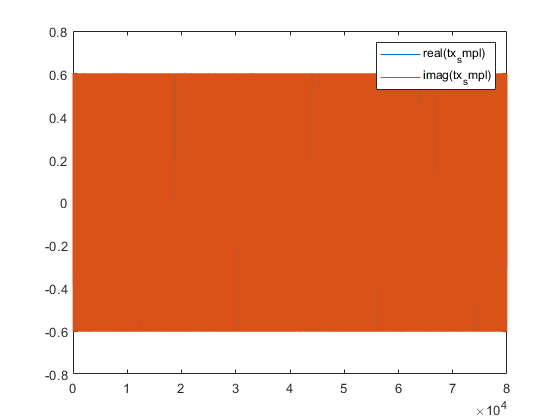

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_gen_mode);
plot(real(tx_smpl))
hold on
plot(imag(tx_smpl))
legend("real(tx_smpl)", "imag(tx_smpl)")
hold off

tx_smpl

tx_smpl =    0.0000 + 0.0000i
   0.0000 + 0.1508i
   0.0000 + 0.3015i
   0.0000 + 0.4523i
   0.0000 + 0.6030i
   0.0000 + 0.4523i
   0.0000 + 0.3015i
   0.0000 + 0.1508i
   0.0000 + 0.0000i
  -0.0000 - 0.1508i


tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1) ; tx_smpl];

rx_smpl = tx_smpl_delayed*exp(1i*chnl_phase_offset);

Eb = Es_avg/k;
snr = 3; %dB
var_noise = Eb/(10^(0.1*snr));
noise_smpl = sqrt(var_noise/2)*randn(length(rx_smpl), 1) + 1i*sqrt(var_noise/2)*randn(length(rx_smpl), 1);
rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.3442 - 0.1816i
   0.0375 - 0.1011i
   0.4685 + 0.1821i
   0.2220 + 0.5621i
   0.8609 + 0.3981i
  -0.1206 + 0.2982i
  -0.6449 + 0.4660i
  -0.2236 + 0.1036i
   0.6906 - 0.0323i
   0.6797 + 0.2813i


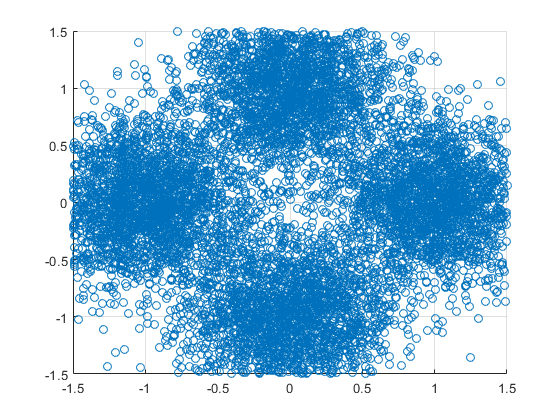

rx_smpl = rx_smpl_noise;
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, rx_type);
scatter(real(rx_sym), imag(rx_sym))
xlim([-1.5 1.5])
ylim([-1.5 1.5])
grid on

if flg_gray_encode
    det_bit = b_gray(det_sym_idx, :);
    det_bit_dec = det_bit(:, 1)*2+det_bit(:, 2);
else
    det_bit = [floor((det_sym_idx-1)/2), mod((det_sym_idx-1), 2)];
end

ser = sum(sym_idx ~= (det_sym_idx-1), 'all')/length(sym_idx)

ser = 0.0454

ber = sum(det_bit ~= b_tx, 'all')/length(b_tx)/2

ber = 0.0228